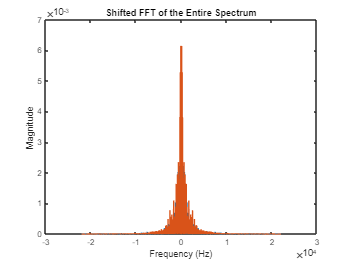

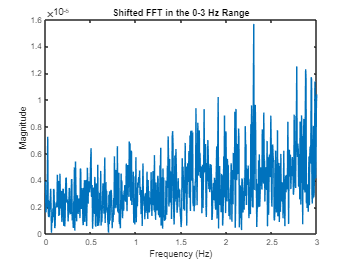

calculatedBPM = BPM("Songs\Viva_La_Vida-Coldplay.mp3");

disp(['Calculated BPM: ', num2str(calculatedBPM)]);

Calculated BPM: 138.0797


function BPM = BPM(song_path)
    [audio_in, audio_freq_sampl] = audioread(song_path);

    Length_audio = length(audio_in);

    df = audio_freq_sampl / Length_audio;

    frequency_audio = -audio_freq_sampl/2:df:audio_freq_sampl/2-df;

    FFT_audio_in = fftshift(fft(audio_in) / Length_audio);

    plot(frequency_audio, abs(FFT_audio_in))
    xlabel('Frequency (Hz)')
    ylabel('Magnitude')
    title('Shifted FFT of the Entire Spectrum')

    f_min = 0;         
    f_max = 3;
    idx_min = find(frequency_audio >= f_min, 1);
    idx_max = find(frequency_audio <= f_max, 1, 'last');

    figure;
    plot(frequency_audio(idx_min:idx_max), abs(FFT_audio_in(idx_min:idx_max)))
    xlabel('Frequency (Hz)')
    ylabel('Magnitude')
    title('Shifted FFT in the 0-3 Hz Range')

    [~, idx_max] = max(abs(FFT_audio_in(idx_min:idx_max)));
    frequency_max_magnitude = frequency_audio(idx_min + idx_max - 1);
    BPM=frequency_max_magnitude*60;
end